# Introduction to wavelet

TODO A little bit of history .....

clearvars;

% parameters 
Fs = 100;
T = 1 / Fs;
L = 250;
Tp = T * L;
F = 1 / Tp;
t = (0:L-1) * T; % time

TODO Considered Domains: I = Z(T)/Z(Tp), Î = Z(F)/Z(Fs) .....

## 1. Frequency content and abrupt changes

TODO explain....

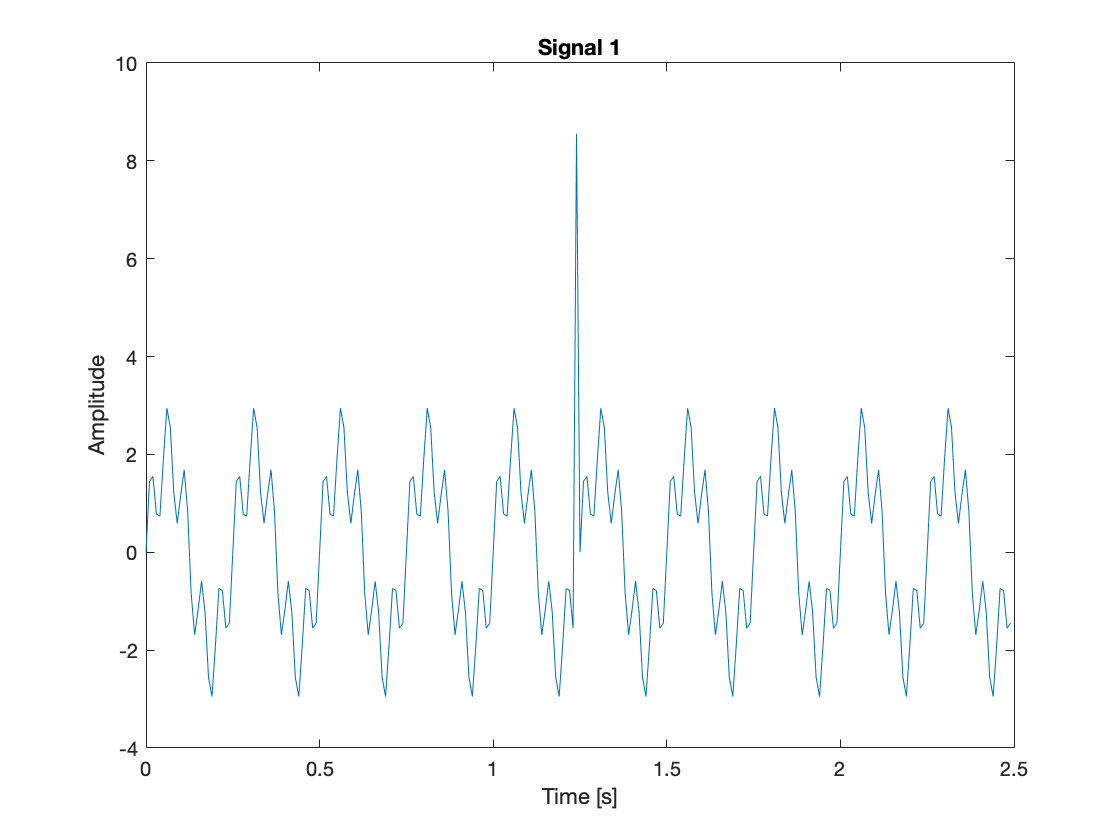

s1 = 2 * sin(2*pi*10*F*t) + sin(2*pi*50*F*t); % two tones
s1(L/2) = s1(L/2) + 10; % and one pulse

plot(t, s1);
title("Signal 1");
xlabel("Time [s]");
ylabel("Amplitude");

%shg;
%pause;

#### FFT Analysis

TODO describe expected .....

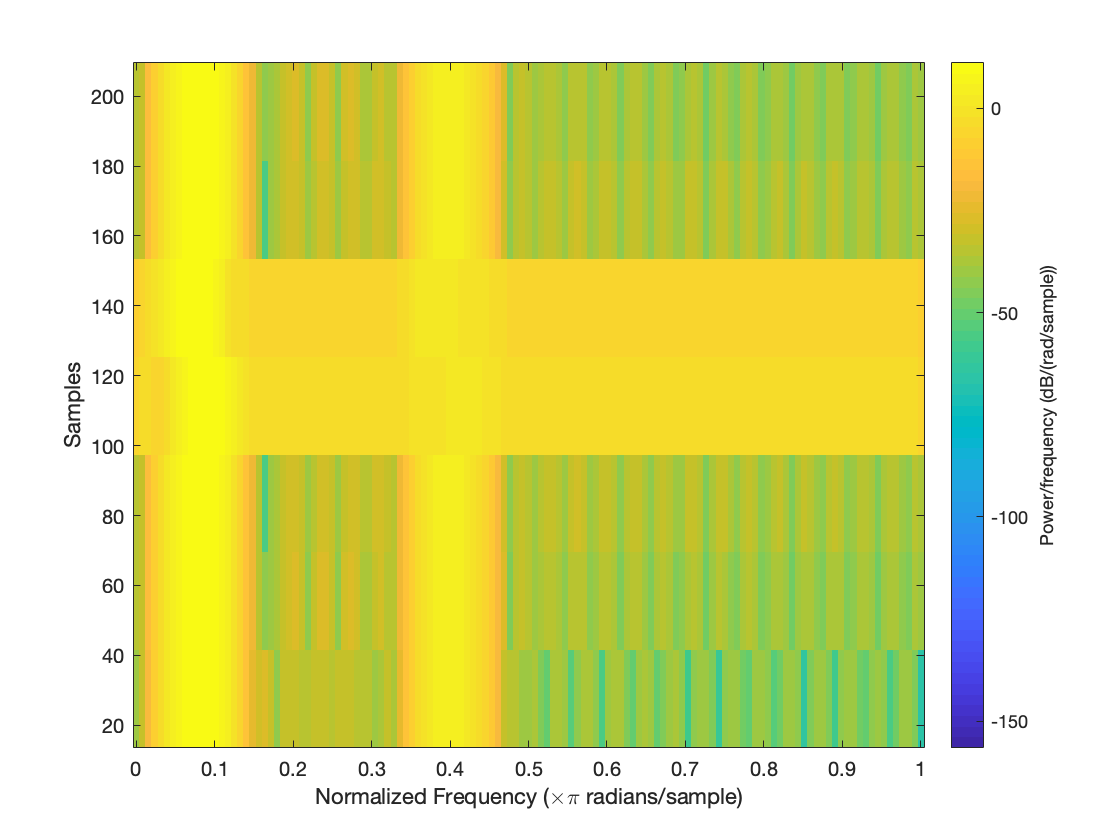

spectrogram(s1);

%shg;
%pause;

#### Wavelet Analysis

TODO describe expected .....

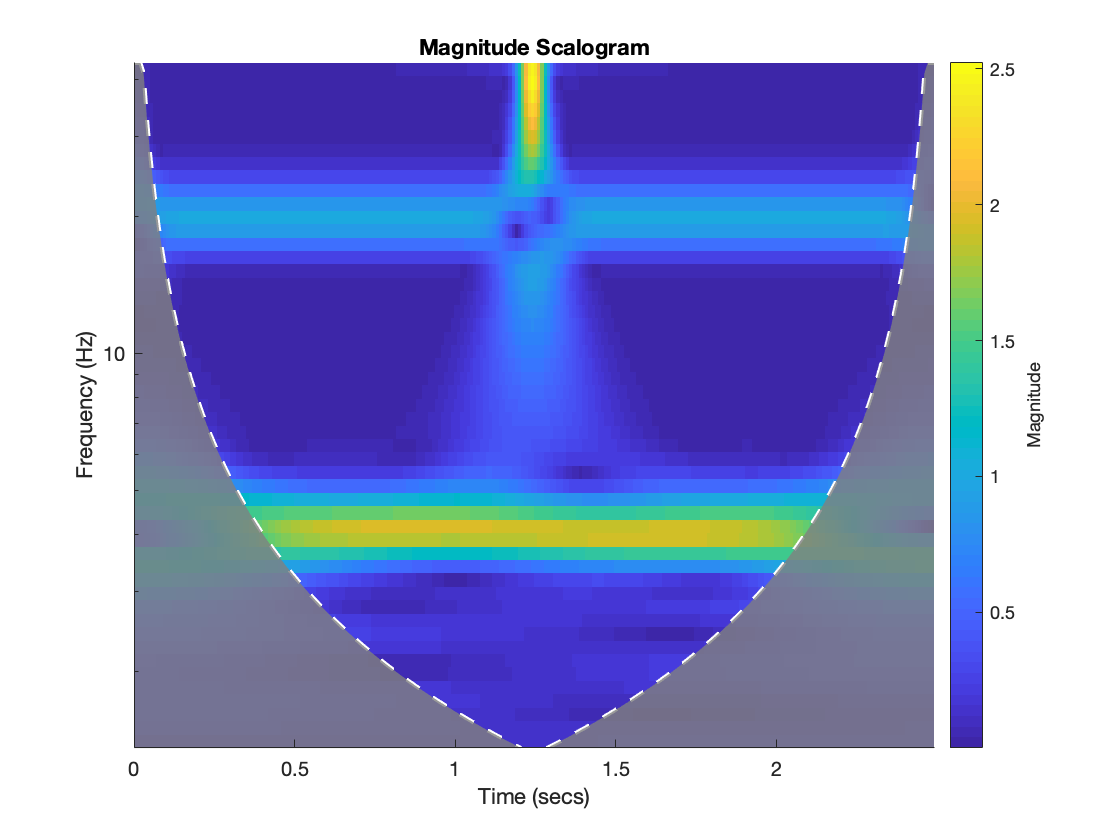

cwt(s1, Fs);

shg;
%pause;

## 2. Pattern over time

TODO explain.... Here we define a sin with exponential increasing frequency

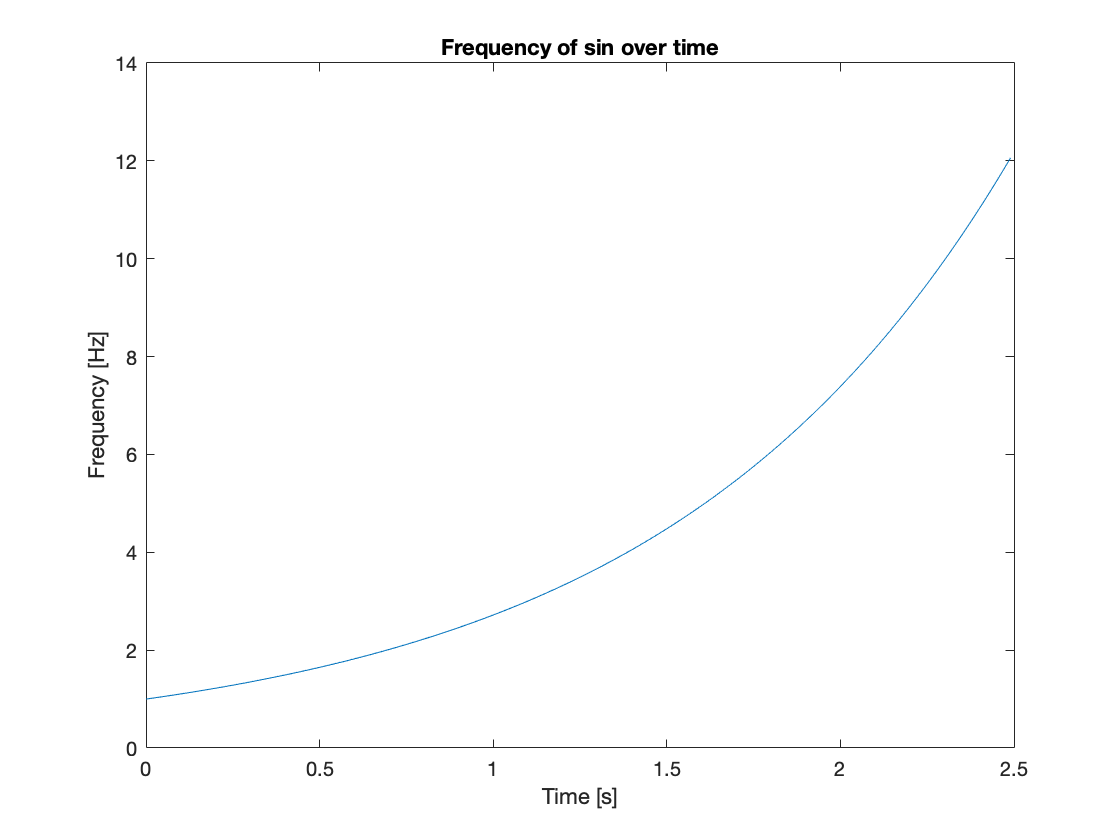

s2_f = exp(t); % signal 2 frequency

% display frequency over time
plot(t, s2_f);
title("Frequency of sin over time");
xlabel("Time [s]");
ylabel("Frequency [Hz]");

%shg;
%pause;

.....

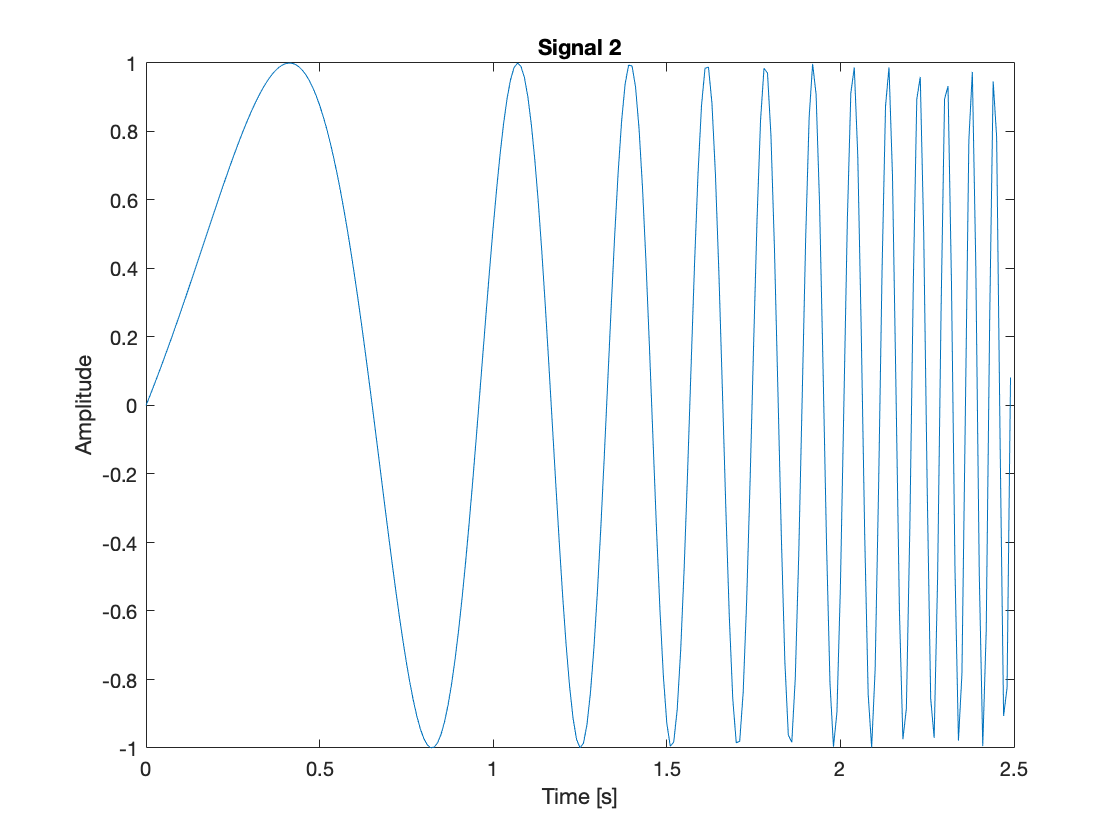

s2 = sin(2*pi*F*s2_f.*t); % signal 2

% display signal 2 over time
plot(t, s2);
title("Signal 2");
ylabel("Amplitude");
xlabel("Time [s]");

%shg;
%pause;

#### FFT Analysis

TODO explain ....

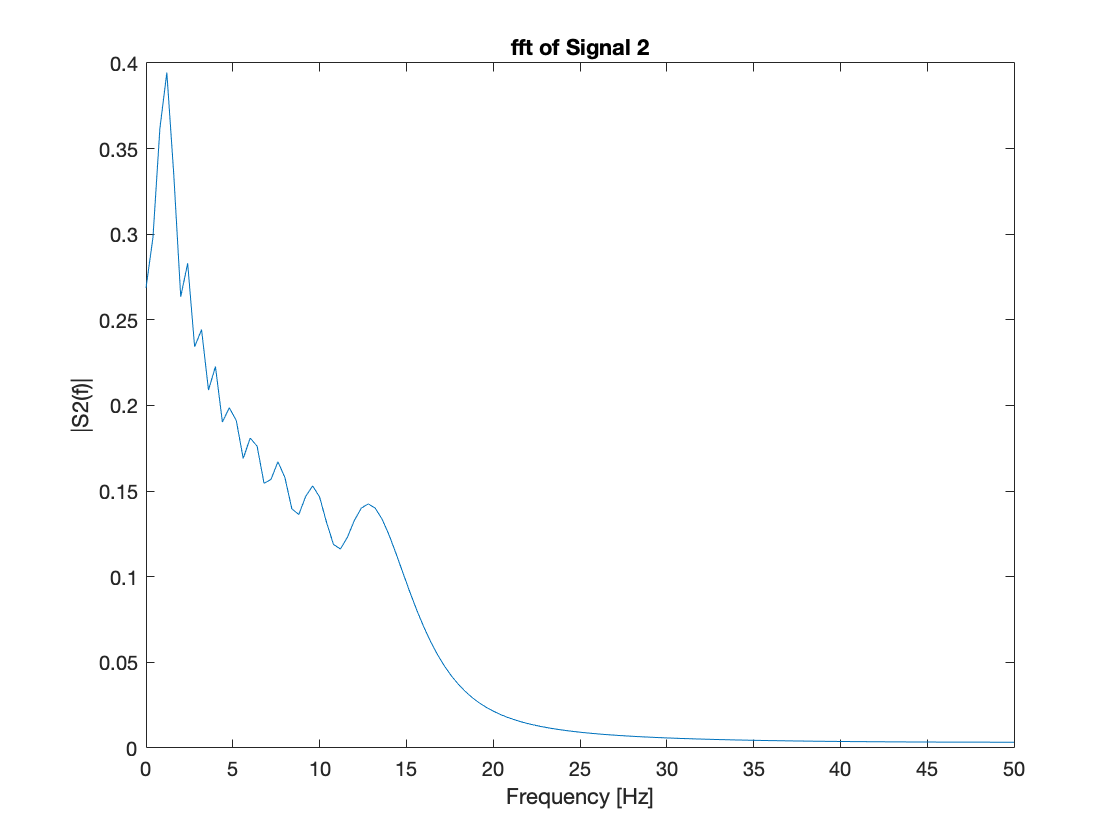

fourier_s2 = T * fft(s2);
f = Fs * (0:L/2) / L;
plot(f, abs(fourier_s2(1:length(f))));
title("fft of Signal 2");
ylabel("|S2(f)|");
xlabel("Frequency [Hz]");

%shg;
%pause;

#### Wavelet Analysis

TODO explain.... frequency is plotted in log scale, so the exponential increasing frequency should result in a line

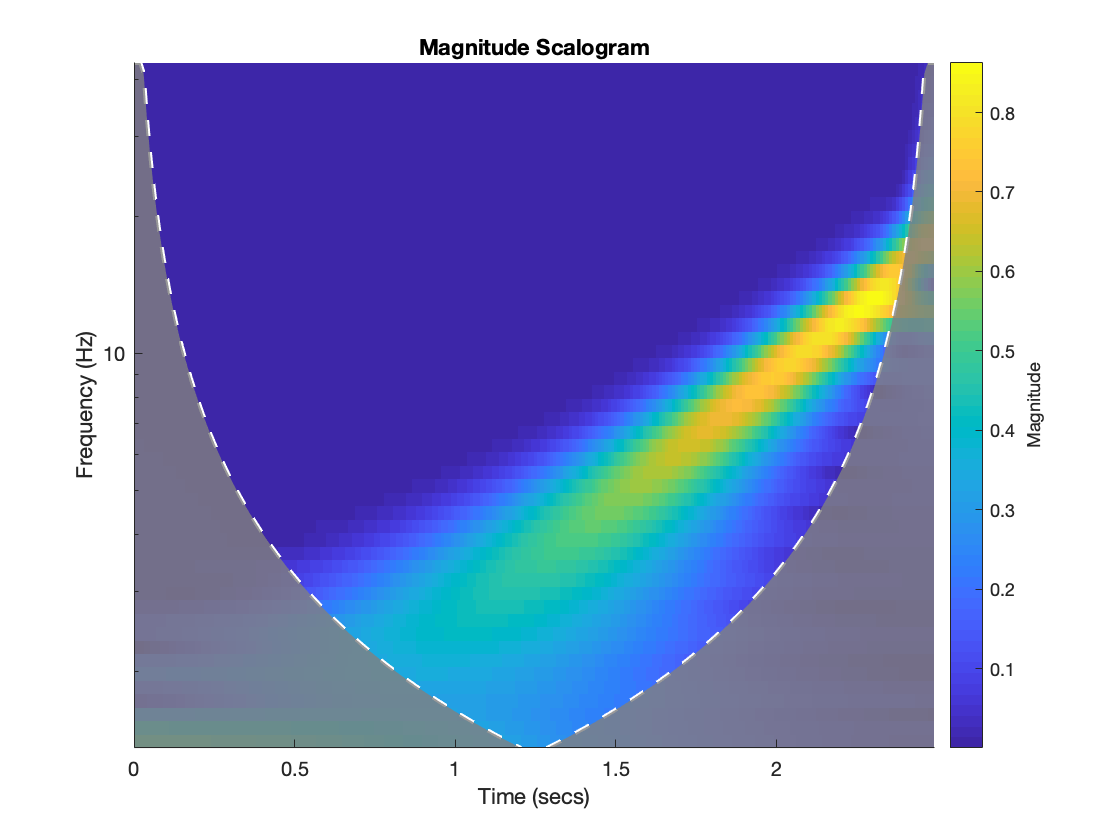

cwt(s2, Fs);

## MRA

TODO explain

figure;
t = -5:0.01:5;
y = t .* 2 .* cos(2 * pi / 3 .* t);
plot(t, y);
hold on;

% ....
% TODO describe constants
indices = 1:size(t,2);

res_1 = 200;
indices_1 = 1:floor(size(t,2) / res_1);
sample_y_1 = y(floor((indices_1 - 1) * res_1 + res_1 / 2));
approx_1 = zeros(size(y));
approx_1(indices) = sample_y_1(ceil(min(indices / res_1, max(indices_1))));

plot(t, approx_1);

res_2 = 100;
indices_2 = 1:floor(size(t,2) / res_2);
sample_y_2 = y(floor((indices_2 - 1) * res_2 + res_2 / 2));
approx_2 = zeros(size(y));
approx_2(indices) = sample_y_2(ceil(min(indices / res_2, max(indices_2))));

plot(t, approx_2);

res_3 = 50;
indices_3 = 1:floor(size(t,2) / res_3);
sample_y_3 = y(floor((indices_3 - 1) * res_3 + res_3 / 2));
approx_3 = zeros(size(y));
approx_3(indices) = sample_y_3(ceil(min(indices / res_3, max(indices_3))));

plot(t, approx_3);